clear
close all
clc

% Load the data from the Excel file
filename = 'Area vs metastable pits'; 
data = xlsread(filename); % Assuming data is in the first sheet

% Extract columns for area and pitting
Area = data(:, 1); % Assuming 'Normalized Area' is the first column
Pitting = data(:, 2); % Assuming 'Pitting' is the second column

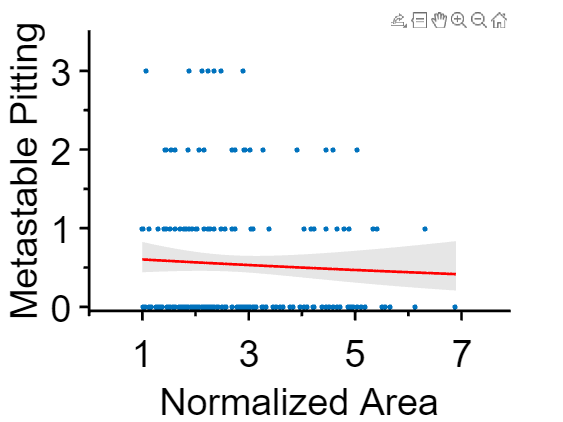

% Plot the raw data (Area vs Pitting, scatter)
figure;
scatter(Area, Pitting, 15, '', 'filled');
% Set the axis limits and ticks based on the data range
xlim([0 7.9])  % Adjust x-axis limits
xticks(1:2:8) 

ylim([-0.05   3.5])  % Adjust y-axis limits
yticks(0:1:3.5)

h = gca; % Get axis to modify
h.XAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.XAxis.MinorTickValues = 0:2:8; % Minor ticks which don't line up with majors

h.YAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.YAxis.MinorTickValues = 0.5:1:3; % Minor ticks which don't line up with majors 

% Format the plot appearance
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 1, ...
    'FontSize', 28, 'linewidth', 2, 'FontWeight', 'normal');

% Label axes
xlabel('Normalized Area', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')
ylabel('Metastable Pitting', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')

hold on

% Fit a logistic regression model to predict pitting based on area
[b, ~, stats] = glmfit(Area, Pitting, 'poisson', 'link', 'log'); 

% Check for overdipersion
% stats.sfit
% Overdispersion parameter is very close to 1, should be ok.

% Generate points for plotting the logistic regression curve
x_vals = linspace(min(Area), max(Area), 100); % Range of Area
[y_vals, dylo, dyhi] = glmval(b, x_vals, 'log', stats, 'confidence', 0.95); % Predicted values with 95% confidence intervals

% Fill the confidence region (shaded area) FIRST
fill([x_vals, fliplr(x_vals)], [y_vals' + dyhi', fliplr(y_vals' - dylo')], [0.9 0.9 0.9], 'EdgeColor', 'none');

% Plot the logistic regression curve (probability of pitting) SECOND
prob_line = plot(x_vals, y_vals, 'LineWidth', 2, 'Color', 'r'); % Red dashed line for the probability curve

% Add a legend for the probability line
%legend(prob_line, 'Poisson Regression', 'FontSize', 20, 'Location', 'northeast');
hold off;